In class exercise on dimensionality reduction

#### Question 1

X = generateSwissRollDataSet(1000); 
scatter3(X(:,1),X(:,2),X(:,3),[],1:length(X(:,1)),'filled');

#### Question 2

What happens if you apply PCA to this dataset, using the `pca` function (`[coeffs,scores,latent] = pca(X)``;`)?    If  you  plot  the  projections  onto the first two eigendirections (`scores`), have you unwrapped the structure?

It looks like we have not unwrapped the structure.

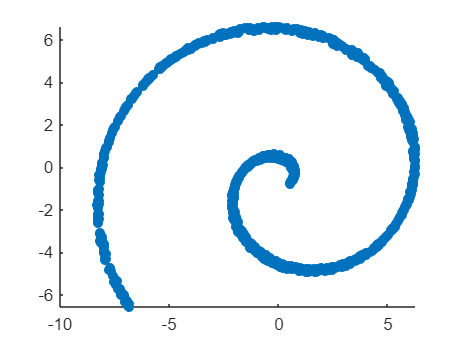

[coeffs,scores,latent] = pca(X);
figure();

scatter(scores(:,1), scores(:,2), 'filled');

#### Question 3 and 4

Now let’s try NMF.  MATLAB has a built-in function for this, with the syntax: `[W,H] =` `nnmf``(X,k)``;` 

where  `k`  is  the  dimensionality  of  the  space  we  would  like  to  create,  `H`  is  a  `k` `x 3 `matrix containing the factors, and `W` is an `N`  `x  k` matrix containing the “projections” (for lack of a better word) onto the rows of `H`.  

You  should  now  apply  NMF  to  the  Swiss  Roll  data  (using  `k=2`).    Plot  the  two columns of `W` against each other.  Did this do any better?  Would you expect it to? 

It doesn't really do any better. Factorization doesn't work, we may need to de-noise the data. 

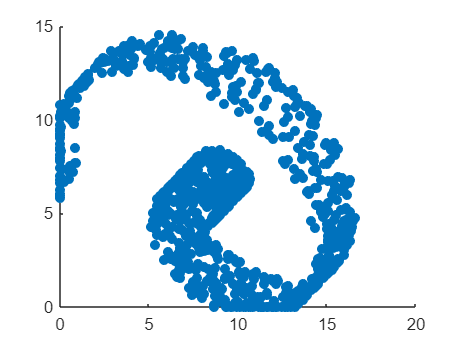

[W,H] = nnmf(X, 2);
scatter(W(:,1), W(:,2), 'filled');

#### Question 5 and 6

Now  try  using  Isomap  on  the  data  set.    This  isn’t  a  built-in  MATLAB  function, but I’ve included code that performs the mapping.  The syntax here is: `[points,vals,usedPoints,dX] = r``unIsomap(``X``,threshold,maxDims``)``;` 

Here,  `threshold`  is  the  number  of  neighboring  points  to  use  in  the  construction 

`maxDims` is the number of dimensions to find, `point``s` is an `N x` `maxDims` matrix of the returned embedding values, `vals` is and array of the first `maxDims` eigenvalues used to calculate the embedding, `usedPoints` is a list of the data points used in the embedding (in case a fully-connected graph is not formed), and `dX` is a sparse `N x`` N`  array giving all of the local connections.  

First,  try  running  Isomap  with  `threshold=``20`,  and  `maxDims=2`.    You  can  plot  the results with: `plotEmbedding``(X,points``)``;` 

The  left  plot  will  be  the  original  data  set  and  the  right  will  be  the  2D  embedded points, with each point colored the same in both plots.  How does the embedding change as you increase `threshold `to 50?  100?  300?  What’s happening here?

Increase threshold = less unwrapping. Aka increase number of neighboring points you look at, the less you unravel and you instead return to the original data.

[points,vals,usedPoints,dX] = runIsomap(X,20,2); 

Finding Distances
Finding Distance for Point #    200
Finding Distance for Point #    400
Finding Distance for Point #    600
Finding Distance for Point #    800
Finding Distance for Point #   1000
Finding Largest Connected Component
Finding Manifold Matrix
Finding Embedding
	Calculating Eigenvalues


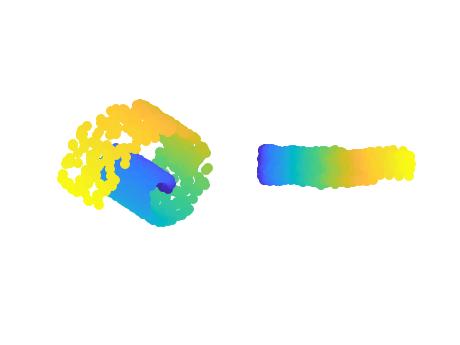

subplot(2,2,1);
plotEmbedding(X,points);

[points1,vals1,usedPoints1,dX1] = runIsomap(X,50,2); 

Finding Distances
Finding Distance for Point #    200
Finding Distance for Point #    400
Finding Distance for Point #    600
Finding Distance for Point #    800
Finding Distance for Point #   1000
Finding Largest Connected Component
Finding Manifold Matrix
Finding Embedding
	Calculating Eigenvalues


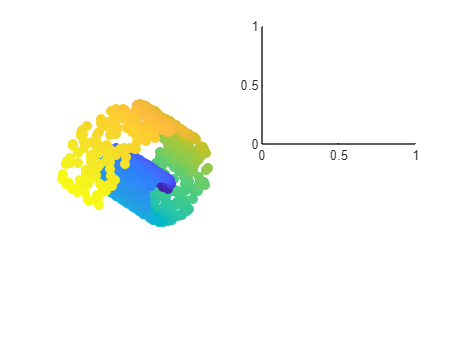

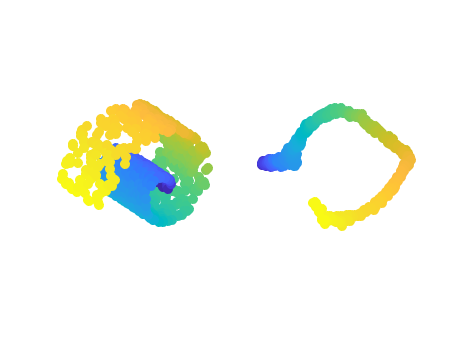

subplot(2,2,2);
plotEmbedding(X,points1);

[points2,vals2,usedPoints2,dX2] = runIsomap(X,100,2); 

Finding Distances
Finding Distance for Point #    200
Finding Distance for Point #    400
Finding Distance for Point #    600
Finding Distance for Point #    800
Finding Distance for Point #   1000
Finding Largest Connected Component
Finding Manifold Matrix
Finding Embedding
	Calculating Eigenvalues


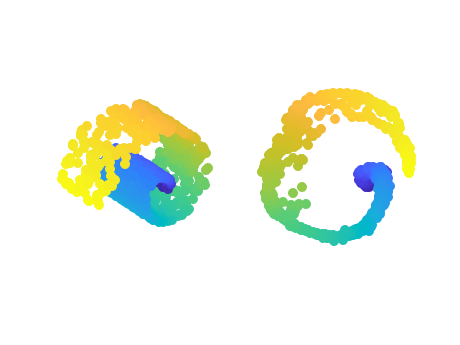

subplot(2,2,3);
plotEmbedding(X,points2);

[points3,vals3,usedPoints3,dX3] = runIsomap(X,300,2); 

Finding Distances
Finding Distance for Point #    200
Finding Distance for Point #    400
Finding Distance for Point #    600
Finding Distance for Point #    800
Finding Distance for Point #   1000
Finding Largest Connected Component
Finding Manifold Matrix
Finding Embedding
	Calculating Eigenvalues


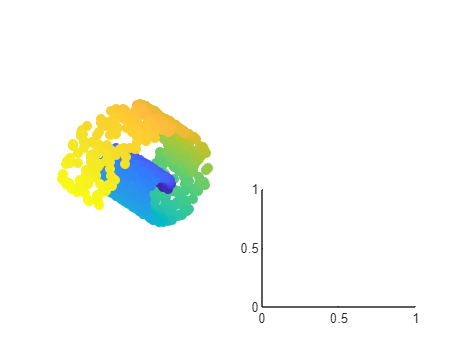

subplot(2,2,4)
plotEmbedding(X,points3);

#### Questions 7 and 8

Lastly, let’s look at how t-SNE does on the Swiss Roll.   To run this, use: `points` `= tsne(X, ``‘``Nu``mDimensions``’``,``dim``,``’``Perplexity``’``,perplexity``)``;` 

Here, `points`, again, is the embedding of `X` into 2D (`N x 2 `array), `NumDimensions` is the dimensionality of the embedding (must be either 2 or 3, but since you have 3D data for now, use `dim``=2`), and `perplexity` is a parameter similar to `threshold` in the Isomap code (higher value -> more neighbors included).  

Run  the  code  with  `perplexity``=30`.    Plot  the  result  using  `plotEmbedding`.    How does  it  compare  to  Isomap?    Try  running  it  again.    What’s  the  same,  what’s different between the runs?

points4 = tsne(X, 2, sim, 30 ,perplexity);

Operation terminated by user during SLStudio.isSLAVTFeatureOn


In simulink.toolstrip.internal.loadConfig

In simulink.toolstrip.internal.refreshConfig

In slCustomizer/refresh

In slCustomizer/callRefresh

In slCustomizer>@()slCustomizer.callRefresh()

In slCustomizer.staticRefresh

In simulinkrc (line 51)
slCustomizer.staticRefresh();

In LiveEditorEvaluationHelperE1726921770 (

plotEmbedding(X,points4);

`...`

`All in all, isomap worked best.`

`Allows you to control how many nearest neighbors you have.`

`It looks at local structure in a global context. `

`You're looking nearby and flattening it out globally, but in order to move through`

`tSNE looks fragmented because you're looking locally but not in a global context`

`But for the next part of the assignment, MNIST, t-SNE worked best. Clustering, only paying attention to local structure because you know they're separate groups. `